# **Modelo Euler-Lagrange Manipulador 4R**

# **Felipe Forero - Iván Hernández - Juan Ramirez - Felipe Zuleta**

## **Eslabón 1**

Se comienza por establecer las funciones de energía para el eslabón 1. Este consiste basicamente en un cuerpo en rotación no centroidal, por lo que su energía cinética se puede calcular de la siguiente forma.


$$K=\frac{1}{2}\cdot I_O \cdot {\overset{\cdot }{q_1 } }^2$$


Donde $I_O$ corresponde al momento inercial del cuerpo alrededor del eje fijo que pasa por O.

Desde el punto de vista de la energía potencial, se define apropiadamente la altura de este centro de masa como el punto de energía cero para el sistema, con lo que el eslabón 1, solo contará con energía cinética.

syms q1(t) qp1(t)
g = 9.81; %[m/s^2]
Io = 0.0055; % [kg-m^2]
K1 = 0.5*Io*qp1.^2

$$K1(t) = \frac{11\,{{\mathrm{qp}}_{1}\left(t\right)}^{2}}{4000}$$

## **Eslabón 2**

Para el segundo eslabón, se comienza por establecer la cinemática directa del centro de masa del eslabón, para lo cual se basa en la cinemática directa del mecanismo tomando en cuenta la longitud del eslabón como su distancia al centro de masa.

syms q2(t) qp2(t)
lc2 = 0.0804; % [m]
T10 = MTH(q1(t),0,0,90,2);
T21 = MTH(q2(t),0,lc2,0,2);
T20 = T10*T21;

De esta forma, la posición del centro de masa del eslabón se encuentra definido por el vector.

posCm2 = T20(1:3,4);

De esta manera, la velocidad del centro de masa del eslabón se define como la derivada temporal de este vector.

v2 = diff(posCm2);
velCm2 = subs(v2,[diff(q1) diff(q2)],[qp1 qp2])

$$velCm2 = \left(\begin{array}{c} -\frac{201\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{1}\left(t\right)\right)\,{\mathrm{qp}}_{1}\left(t\right)}{2500}-\frac{201\,\cos\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\,{\mathrm{qp}}_{2}\left(t\right)}{2500}\\ \frac{201\,\cos\left(q_{1}\left(t\right)\right)\,\cos\left(q_{2}\left(t\right)\right)\,{\mathrm{qp}}_{1}\left(t\right)}{2500}-\frac{201\,\sin\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\,{\mathrm{qp}}_{2}\left(t\right)}{2500}\\ \frac{201\,\cos\left(q_{2}\left(t\right)\right)\,{\mathrm{qp}}_{2}\left(t\right)}{2500} \end{array}\right)$$

Y de esta forma, la energía cinética traslacional del eslabón se define a continuación

m2 = 0.1520; % [kg]
K21 = 0.5*m2*(velCm2'*velCm2)

$$K21 = \begin{array}{l} \frac{19\,\left(\frac{201\,\cos\left(q_{1}\left(t\right)\right)\,\cos\left(q_{2}\left(t\right)\right)\,{\mathrm{qp}}_{1}\left(t\right)}{2500}-\frac{201\,\sin\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\,{\mathrm{qp}}_{2}\left(t\right)}{2500}\right)\,\left(\frac{201\,\bar{{\mathrm{qp}}_{1}\left(t\right)}\,\sigma_{4}\,\sigma_{1}}{2500}-\frac{201\,\bar{{\mathrm{qp}}_{2}\left(t\right)}\,\sigma_{3}\,\sigma_{2}}{2500}\right)}{250}+\frac{19\,\left(\frac{201\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{1}\left(t\right)\right)\,{\mathrm{qp}}_{1}\left(t\right)}{2500}+\frac{201\,\cos\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\,{\mathrm{qp}}_{2}\left(t\right)}{2500}\right)\,\left(\frac{201\,\bar{{\mathrm{qp}}_{1}\left(t\right)}\,\sigma_{1}\,\sigma_{3}}{2500}+\frac{201\,\bar{{\mathrm{qp}}_{2}\left(t\right)}\,\sigma_{4}\,\sigma_{2}}{2500}\right)}{250}+\frac{767619\,\cos\left(q_{2}\left(t\right)\right)\,\bar{{\mathrm{qp}}_{2}\left(t\right)}\,\sigma_{1}\,{\mathrm{qp}}_{2}\left(t\right)}{1562500000}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\bar{q_{2}\left(t\right)}\right)\\ \sigma_{2}=\sin\left(\bar{q_{2}\left(t\right)}\right)\\ \sigma_{3}=\sin\left(\bar{q_{1}\left(t\right)}\right)\\ \sigma_{4}=\cos\left(\bar{q_{1}\left(t\right)}\right) \end{array}$$

Por otra parte, la energía cinética rotacional del cuerpo se define a partir del momento de inercia respecto a su centro de masa

Icm2 = 7.0682e-04;% [kg-m^2]
K22 = 0.5*Icm2*qp2.^2

$$K22(t) = \frac{6519263823089693\,{{\mathrm{qp}}_{2}\left(t\right)}^{2}}{18446744073709551616}$$

De esta manera, la energía cinética del cuerpo se define a continuación

K2 = simplify(K21+K22)

$$K2(t) = \begin{array}{l} \frac{19\,\left(\frac{201\,\cos\left(q_{1}\left(t\right)\right)\,\cos\left(q_{2}\left(t\right)\right)\,{\mathrm{qp}}_{1}\left(t\right)}{2500}-\frac{201\,\sin\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\,{\mathrm{qp}}_{2}\left(t\right)}{2500}\right)\,\left(\frac{201\,\bar{{\mathrm{qp}}_{1}\left(t\right)}\,\sigma_{4}\,\sigma_{1}}{2500}-\frac{201\,\bar{{\mathrm{qp}}_{2}\left(t\right)}\,\sigma_{3}\,\sigma_{2}}{2500}\right)}{250}+\frac{19\,\left(\frac{201\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{1}\left(t\right)\right)\,{\mathrm{qp}}_{1}\left(t\right)}{2500}+\frac{201\,\cos\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\,{\mathrm{qp}}_{2}\left(t\right)}{2500}\right)\,\left(\frac{201\,\bar{{\mathrm{qp}}_{1}\left(t\right)}\,\sigma_{1}\,\sigma_{3}}{2500}+\frac{201\,\bar{{\mathrm{qp}}_{2}\left(t\right)}\,\sigma_{4}\,\sigma_{2}}{2500}\right)}{250}+\frac{6519263823089693\,{{\mathrm{qp}}_{2}\left(t\right)}^{2}}{18446744073709551616}+\frac{767619\,\cos\left(q_{2}\left(t\right)\right)\,\bar{{\mathrm{qp}}_{2}\left(t\right)}\,\sigma_{1}\,{\mathrm{qp}}_{2}\left(t\right)}{1562500000}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\bar{q_{2}\left(t\right)}\right)\\ \sigma_{2}=\sin\left(\bar{q_{2}\left(t\right)}\right)\\ \sigma_{3}=\sin\left(\bar{q_{1}\left(t\right)}\right)\\ \sigma_{4}=\cos\left(\bar{q_{1}\left(t\right)}\right) \end{array}$$

Por otra parte, la energía potencial del cuerpo se encuentra estrechamente relacionada con su posición sobre la vertical, así.

U2 = m2*posCm2(3)*g

$$U2 = \frac{3746439\,\sin\left(q_{2}\left(t\right)\right)}{31250000}$$

## Eslabón 3

Para el caso del tercer eslabón se sigue un proceso análogo al realizado con el segundo eslabón

syms q3(t) qp3(t)
l2 = 0.1798; % [m]
lc3 = 0.0537; % [m]
T10 = MTH(q1(t),0,0,90,2);
T21 = MTH(q2(t),0,l2,0,2);
T32 = MTH(q3(t),0,lc3,0,2);
T30 = T10*T21*T32;

Se define el vector de posición, y seguidamente el vector de velocidad lineal del centro de masa de este eslabón.

posCm3 = T30(1:3,4);
v3 = diff(posCm3);
velCm3 = subs(v3,[diff(q1) diff(q2) diff(q3)],[qp1 qp2 qp3])

La energía cinética traslacional del eslabón se define a continuación

m3 = 0.2790; %[kg]
K31 = 0.5*m3*(velCm3'*velCm3)

Adicionalmente la energía cinética rotacional del cuerpo se define a partir del momento de inercia respecto a su centro de masa

Icm3 = 0.0011; %[kg*m^2]
K32 = 0.5*Icm3*qp3.^2

$$K32(t) = \frac{11\,{{\mathrm{qp}}_{3}\left(t\right)}^{2}}{20000}$$

De esta manera, la energía cinética del cuerpo se define a continuación

K3 = simplify(K31+K32)

Finalmente, la energía potencial del cuerpo se define

U3 = m3*posCm3(3)*g

$$U3 = \frac{246055401\,\sin\left(q_{2}\left(t\right)\right)}{500000000}+\frac{146976363\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{3}\left(t\right)\right)}{1000000000}+\frac{146976363\,\cos\left(q_{3}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)}{1000000000}$$

## Eslabón 4

Para este eslabón se requiere el mismo procedimiento ya explicado para los dos eslabones anteriores.

syms q4(t) qp4(t) 
l3 = 0.1253; % [m]
lc4 = 4;
e = 0.05; %[m]
T10 = MTH(q1(t),0,0,90,2);
T21 = MTH(q2(t),0,l2,0,2);
T32 = MTH(q3(t),0,l3,0,2);
T43 = MTH(q4(t),e,lc4,0,2);
T40 = T10*T21*T32*T43;

Se define el vector de posición, y seguidamente el vector de velocidad lineal del centro de masa de este eslabón.

posCm4 = T40(1:3,4);
v4 = diff(posCm4)

velCm4 = subs(v4,[diff(q1) diff(q2) diff(q3) diff(q4)],[qp1 qp2 qp3 qp4])

La energía cinética traslacional del eslabón se define a continuación

m4 = 8;
K41 = 0.5*m4*(velCm4'*velCm4)

Adicionalmente la energía cinética rotacional del cuerpo se define a partir del momento de inercia respecto a su centro de masa

Icm4 = 8;
q4punto = diff(q4(t))

$$q4punto = \frac{\partial }{\partial t}q_{4}\left(t\right)$$

K42 = 0.5*Icm4*q4punto.^2

$$K42 = 4\,{\left(\frac{\partial }{\partial t}q_{4}\left(t\right)\right)}^{2}$$

De esta manera, la energía cinética del cuerpo se define a continuación

K4 = K41+K42

Finalmente, la energía potencial del cuerpo se define

U4 = m4*posCm4(3)*g

$$U4 = \frac{881919\,\sin\left(q_{2}\left(t\right)\right)}{62500}+\frac{1229193\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{3}\left(t\right)\right)}{125000}+\frac{1229193\,\cos\left(q_{3}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)}{125000}+\frac{7848\,\cos\left(q_{4}\left(t\right)\right)\,\left(\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{3}\left(t\right)\right)+\cos\left(q_{3}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\right)}{25}-\frac{7848\,\sin\left(q_{4}\left(t\right)\right)\,\left(\sin\left(q_{2}\left(t\right)\right)\,\sin\left(q_{3}\left(t\right)\right)-\cos\left(q_{2}\left(t\right)\right)\,\cos\left(q_{3}\left(t\right)\right)\right)}{25}$$

## Lagrangiano

Se define ahora el lagrangiano del manipulador


$$L=K-U$$


K = K1+ K2 +K3; % +K4; Se omite por usar un servo
U = U2+ U3;% +U4; se omite por usar un servo
L = K-U;

## Variables generalizadas

syms qpp1 qpp2 qpp3 t1 t2 t3 tt1 tt2 tt3 ttt1 ttt2 ttt3
format short
(3819*cos(conj(t1))*cos(conj(t2))*((201*cos(t2)*sin(t1)*tt1^2)/2500 + (201*cos(t1)*sin(t2)*tt1*tt2)/1250 + (201*cos(t2)*sin(t1)*tt2^2)/2500 - (201*ttt1*cos(t1)*cos(t2))/2500 + (201*ttt2*sin(t1)*sin(t2))/2500))/625000

$$ans = \frac{3819\,\cos\left(\bar{t_{1}}\right)\,\cos\left(\bar{t_{2}}\right)\,\left(\frac{201\,\cos\left(t_{2}\right)\,\sin\left(t_{1}\right)\,{{\mathrm{tt}}_{1}}^{2}}{2500}+\frac{201\,\cos\left(t_{1}\right)\,\sin\left(t_{2}\right)\,{\mathrm{tt}}_{1}\,{\mathrm{tt}}_{2}}{1250}+\frac{201\,\cos\left(t_{2}\right)\,\sin\left(t_{1}\right)\,{{\mathrm{tt}}_{2}}^{2}}{2500}-\frac{201\,{\mathrm{ttt}}_{1}\,\cos\left(t_{1}\right)\,\cos\left(t_{2}\right)}{2500}+\frac{201\,{\mathrm{ttt}}_{2}\,\sin\left(t_{1}\right)\,\sin\left(t_{2}\right)}{2500}\right)}{625000}$$

tau1 = diff(diff(L,qp1))-diff(L,q1);
tau1 = subs(tau1,[diff(q1) diff(qp1) diff(q2) diff(qp2) diff(q3) diff(qp3)],[qp1 qpp1 qp2 qpp2 qp3 qpp3]);
tau1 = subs(tau1,[q1 q2 q3],[t1 t2 t3]);
tau1 = subs(tau1,[qp1 qp2 qp3],[tt1 tt2 tt3]);
tau1 = subs(tau1,[qpp1 qpp2 qpp3],[ttt1 ttt2 ttt3])


tau2 = diff(diff(L,qp2))-diff(L,q2);
tau2 = subs(tau2,[diff(q1) diff(qp1) diff(q2) diff(qp2) diff(q3) diff(qp3)],[qp1 qpp1 qp2 qpp2 qp3 qpp3]);
tau2 = subs(tau2,[q1 q2 q3],[t1 t2 t3]);
tau2 = subs(tau2,[qp1 qp2 qp3],[tt1 tt2 tt3]);
tau2 = subs(tau2,[qpp1 qpp2 qpp3],[ttt1 ttt2 ttt3])


tau3 = diff(diff(L,qp3))-diff(L,q3);
tau3 = subs(tau3,[diff(q1) diff(qp1) diff(q2) diff(qp2) diff(q3) diff(qp3)],[qp1 qpp1 qp2 qpp2 qp3 qpp3]); + (537*cos(conj(t1))*cos(conj(t2))*sin(conj(t3)))/10000

$$ans = \frac{537\,\cos\left(\bar{t_{1}}\right)\,\cos\left(\bar{t_{2}}\right)\,\sin\left(\bar{t_{3}}\right)}{10000}$$

tau3 = subs(tau3,[q1 q2 q3],[t1 t2 t3]);
tau3 = subs(tau3,[qp1 qp2 qp3],[tt1 tt2 tt3]);
tau3 = subs(tau3,[qpp1 qpp2 qpp3],[ttt1 ttt2 ttt3])

%tau1 = simplify(tau1)
%tau2 = simplify(tau2)
%tau3 = simplify(tau3)

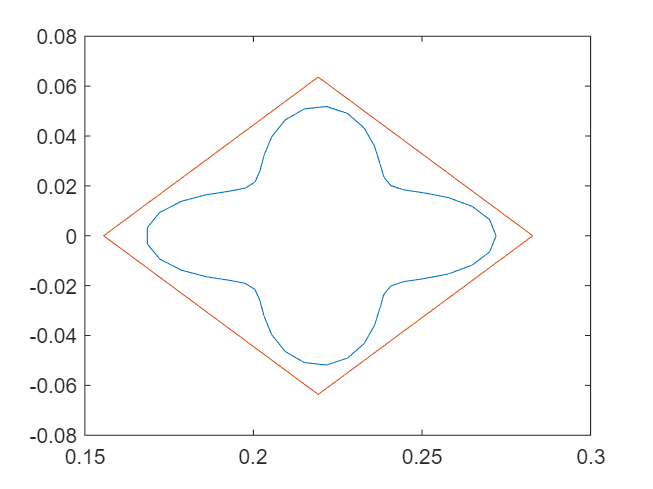

[r,theta] = trayectoria0(pi/4,80e-3,1,3.5,4,50);
[xFree,yFree] = Totrigen(220e-3,0,theta,r);
xCC3 = 220e-3;
yCC3 = 0;
R = 90e-3;
[xC3, yC3] = cuadr(200e-3*sqrt(2),0,R,5);

figure()
plot(xFree,yFree)
hold on
plot(xC3,yC3)

q0 = [0, 101.10 -165 0];

qFreeT = zeros(length(xFree)+3,4);
qFreeT(1,:) = q0;
qFreeL = zeros(length(xC3)+3,4);
qFreeL(end,:) = q0;
zD = 0.03;


for i=2:length(qFreeT)-1
    if(i==2)
        param = [xFree(1), yFree(1), zD+0.050,0,0];
    elseif(i==(length(qFreeT)-1))
        param = [xFree(end), yFree(end), zD+0.05,0,0];
    else
        param = [xFree(i-2), yFree(i-2), zD,0,0];
    end
    [q1V, q2V, q3V, q4V] = inverseKinematics(param(1,1), param(1,2), param(1,3), param(1,4), param(1,5));
    qFreeT(i,:) = [q1V, q2V, q3V, q4V];
end

for i = 1:length(qFreeL)-1
    if(i==1)
        param = [xC3(1), yC3(1), zD+0.050,0,0];
    elseif(i==(length(qFreeL)-1))
        param = [xC3(end), yC3(end), zD+0.050,0,0];
    elseif(i==(length(qFreeL)-2))
        param = [xC3(end), yC3(end), zD,0,0];
    else
        param = [xC3(i-1), yC3(i-1), zD,0,0];
    end

    [q1V, q2V, q3V, q4V] = inverseKinematics(param(1,1), param(1,2), param(1,3), param(1,4), param(1,5));
    qFreeL(i,:) = [q1V, q2V, q3V, q4V];
end
qFree = [qFreeT;qFreeL];

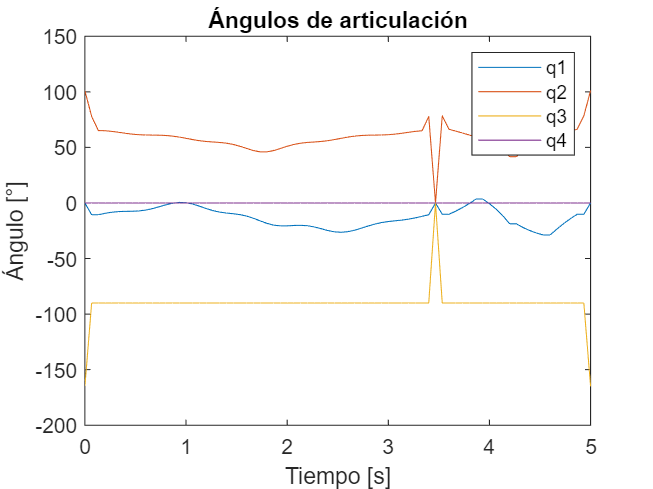

close all;

q1Val = qFree(:,1)';
q2Val = qFree(:,2)';
q3Val = qFree(:,3)';
q4Val = qFree(:,4)';

figure()
time = linspace(0,5,length(qFree(:,1)));
plot(time,q1Val);
hold on
plot(time,q2Val);
plot(time,q3Val);
plot(time,q4Val);
legend('q1','q2','q3','q4')
title('Ángulos de articulación');
xlabel('Tiempo [s]')
ylabel('Ángulo [°]')


deltaT = time(2)-time(1);

q1Val = q1Val*(pi()/180);
q2Val = q2Val*(pi()/180);
q3Val = q3Val*(pi()/180);

q1pVal = [0 diff(q1Val)/deltaT];
q1p2Val = [0 diff(q1pVal)/deltaT];

q2pVal = [0 diff(q2Val)/deltaT];
q2p2Val =[0 diff(q2pVal)/deltaT];

q3pVal = [0 diff(q3Val)/deltaT];
q3p2Val =[0 diff(q3pVal)/deltaT];

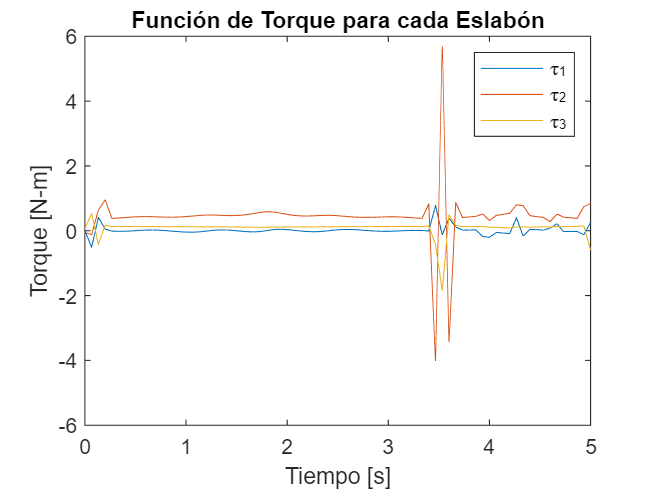

Tau1 = zeros(length(q1Val),1);
Tau2 = zeros(length(q1Val),1);
Tau3 = zeros(length(q1Val),1);
for i = 1:length(q1Val)
    Tau1(i) = double(subs(tau1,[t1 t2 t3 tt1 tt2 tt3 ttt1 ttt2 ttt3],[q1Val(i) q2Val(i) q3Val(i) q1pVal(i) q2pVal(i) q3pVal(i) q1p2Val(i) q2p2Val(i) q3p2Val(i)]));
    Tau2(i) = double(subs(tau2,[t1 t2 t3 tt1 tt2 tt3 ttt1 ttt2 ttt3],[q1Val(i) q2Val(i) q3Val(i) q1pVal(i) q2pVal(i) q3pVal(i) q1p2Val(i) q2p2Val(i) q3p2Val(i)]));
    Tau3(i) = double(subs(tau3,[t1 t2 t3 tt1 tt2 tt3 ttt1 ttt2 ttt3],[q1Val(i) q2Val(i) q3Val(i) q1pVal(i) q2pVal(i) q3pVal(i) q1p2Val(i) q2p2Val(i) q3p2Val(i)]));
end

%Tau1 = double(subs(tau1,[q1 q2 q3 qp1 qp2 qp3 qpp1 qpp2 qpp3],[q1Val q2Val q3Val q1pVal q2pVal q3pVal q1p2Val q2p2Val q3p2Val]))
%Tau1 = double(subs(tau1,[t1 t2 t3 tt1 tt2 tt3], [q1Val(1) q2Val(1) q3Val(1) q1pVal(1) q2pVal(1) q3pVal(1)]))
%Tau1 = (subs(Tau1,[qp1 qp2 qp3], [q1pVal(1) q2pVal(1) q3pVal(1)]))

figure()
plot(time,Tau1)
hold on
plot(time,Tau2)
plot(time,Tau3)
legend('\tau_1', '\tau_2', '\tau_3')
title('Función de Torque para cada Eslabón');
xlabel('Tiempo [s]')
ylabel('Torque [N-m]')